clc; clear; close all;

## Lab 2 MATLAB Frequency Plan

Fs = 225e6;
F  = 14e6;
F1 = 25e6;
F2 = 61e6;
F3 = 101e6;
F4 = 110.5e6;
f = F/Fs;
f1 = F1/Fs;
f2 = F2/Fs;
f3 = F3/Fs;
f4 = F4/Fs;

## create time-sample-based x-axis

FFT = 16;
% bin_width = 7e6; % Hz
% FFT = (Fs/2)/bin_width
n1 = 0;
n2 = FFT;
n = n1:n2-1;
bin_width = ((Fs/2) / FFT) / 1e6

bin_width = 7.0312

## Create Discrete-time signal

xn = cos(2*pi*f*n);
xn1 = cos(2*pi*f1*n);
xn2 = cos(2*pi*f2*n);
xn3 = cos(2*pi*f3*n);
xn4 = cos(2*pi*f4*n);

## Compute FFT in Discrete Time

Xk = fft(xn, FFT);
Xk1 = fft(xn1, FFT);
Xk2 = fft(xn2, FFT);
Xk3 = fft(xn3, FFT);
Xk4 = fft(xn4, FFT);

## Create magnitude spectrum

magXk = abs(Xk);
magXk = magXk/max(magXk); % normalize
% magXk_sqr = magXk.^2;
dBXk = 10 * log10(magXk);

magXk1 = abs(Xk1);
magXk1 = magXk1/max(magXk1);
dBXk1 = 10 * log10(magXk1);

magXk2 = abs(Xk2);
magXk2 = magXk2/max(magXk2);
dBXk2 = 10 * log10(magXk2);

magXk3 = abs(Xk3);
magXk3 = magXk3/max(magXk3);
dBXk3 = 10 * log10(magXk3);

magXk4 = abs(Xk4);
magXk4 = magXk4/max(magXk4);
dBXk4 = 10 * log10(magXk4);

## Map FFT Output to Real Frequency

S = [dBXk(1:FFT/2)];
S1 = [dBXk1(1:FFT/2)];
S2 = [dBXk2(1:FFT/2)];
S3 = [dBXk3(1:FFT/2)];
S4 = [dBXk4(1:FFT/2)];

sn = 1:FFT/2;
nn = Fs*sn*(1/FFT);

## Plots

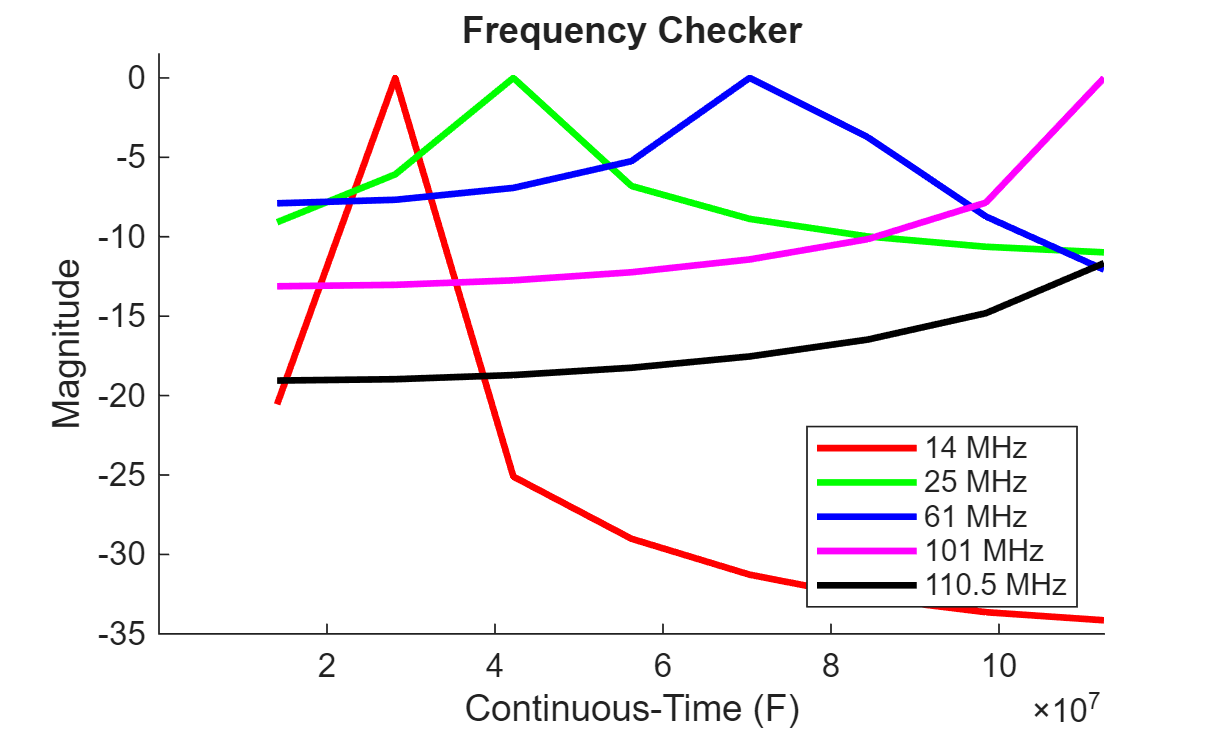

hold on;
plot(nn, S, 'm', 'LineWidth', 2, 'Color', 'red');
plot(nn, S1, 'm', 'LineWidth', 2, 'Color', 'green');
plot(nn, S2, 'm', 'LineWidth', 2, 'Color', 'blue');
plot(nn, S3, 'm', 'LineWidth', 2, 'Color', 'magenta');
plot(nn, S4, 'm', 'LineWidth', 2, 'Color', 'black');
ylim([-35 1.5]);
xlim([1 Fs/2]);
legend('14 MHz', '25 MHz', '61 MHz', '101 MHz', '110.5 MHz', 'Location','SouthEast')
xlabel('Continuous-Time (F)');
ylabel('Magnitude');
title('Frequency Checker');
hold off;